#### Exercicios metodo de Euler

#### 1)

clear all
syms y(t)
f=@(t,y) y+exp(t)

f = function_handle with value:
    @(t,y)y+exp(t)


n=10

n =     10


h=0.1

h =    0.100000000000000


t0=1

t0 =      1


y0=0.1

y0 =    0.100000000000000


t=[1,n];
y=[1,n];
t(1)=t0;
y(1)=y0;
hold on
for i=1:n
    y(i+1)=y(i)+h*f(t(i),y(i));
    t(i+1)=t(i)+h;
    disp([i,t(i+1),y(i+1)])
end

   1.000000000000000   1.100000000000000   0.381828182845905

   2.000000000000000   1.200000000000000   0.720427603525138

   3.000000000000000   1.300000000000000   1.124482056151307

   4.000000000000000   1.400000000000000   1.603859928528362

   5.000000000000000   1.500000000000000   2.169765918065666

   6.000000000000000   1.600000000000001   2.834911416906039

   7.000000000000000   1.700000000000001   3.613705801036155

   8.000000000000000   1.800000000000001   4.522471120312491

   9.000000000000000   1.900000000000001   5.579682978785035

  10.000000000000000   2.000000000000001   6.806240720891466



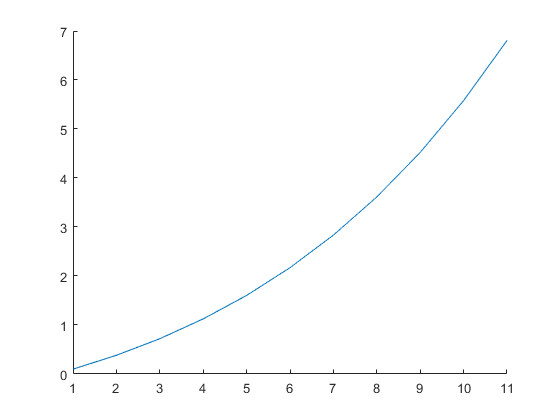

plot(y)
hold off

syms y(t)
edo1=diff(y(t),t)==y+exp(t)

$$edo1(t) = \frac{\partial }{\partial t}y\left(t\right)={\mathrm{e}}^{t}+y\left(t\right)$$

a=dsolve(edo1,y(1)==0.1)

$$a = {\mathrm{e}}^{t}\,\left(\frac{{\mathrm{e}}^{-1}}{10}-1\right)+t\,{\mathrm{e}}^{t}$$

simplify(a)

$$ans = {\mathrm{e}}^{t-1}\,\left(t\,\mathrm{e}-\mathrm{e}+\frac{1}{10}\right)$$

clear all
syms y(t)
f=@(t,y) y+exp(t)

f = function_handle with value:
    @(t,y)y+exp(t)


n=10

n =     10


h=0.1

h =    0.100000000000000


t0=1

t0 =      1


y0=0.1

y0 =    0.100000000000000


t=[1,n];
y=[1,n];
t(1)=t0;
y(1)=y0;
phi=@(t) exp(t-1).*(t.*exp(1.0)-exp(1.0)+0.1);
disp('i t[i] y[i] phi(t[i]) erro')

i t[i] y[i] phi(t[i]) erro


for i=1:n
    y(i+1)=y(i)+h*f(t(i),y(i));
    t(i+1)=t(i)+h;
    erro=abs(y(i+1)-phi(t(i+1)));
    disp([i,t(i+1),y(i+1),phi(t(i+1)),erro])
end

   1.000000000000000   1.100000000000000   0.381828182845905   0.410933694202208   0.029105511356304

   2.000000000000000   1.200000000000000   0.720427603525138   0.786163660363327   0.065736056838189

   3.000000000000000   1.300000000000000   1.124482056151307   1.235774881043375   0.111292824892068

   4.000000000000000   1.400000000000000   1.603859928528362   1.771262456501999   0.167402527973637

   5.000000000000000   1.500000000000000   2.169765918065666   2.405716662239049   0.235950744173383

   6.000000000000000   1.600000000000001   2.834911416906039   3.154031334676125   0.319119917770085

   7.000000000000000   1.700000000000001   3.613705801036155   4.033138444956094   0.419432643919939

   8.000000000000000   1.800000000000001   4.522471120312491   5.062272064379613   0.539800944067122

   9.000000000000000   1.900000000000001   5.579682978785035   6.263265309167049   0.683582330382014

  10.000000000000000   2.000000000000001   6.806240720891466   7.660884281776570  

phi=@(t) exp(t-1).*(t.*exp(1.0)-exp(1.0)+0.1)

phi = function_handle with value:
    @(t)exp(t-1).*(t.*exp(1.0)-exp(1.0)+0.1)


erro_absoluto=abs(y(11)-phi(2.0))

erro_absoluto =    0.854643560885091



plot(5:0.1:6,y,'color',[1.0,0.0,0.0])
plot(5:0.1:6,phi(t),'color',[0.0,0.0,1.0])
hold off

hold on
plot(5:0.1:6,y,'color',[1.0,0.0,0.0])
plot(5:0.1:6,phi(t),'color',[0.0,0.0,1.0])
hold off

clear all
syms y(t)
f=@(y,t) y+exp(t)

f = function_handle with value:
    @(y,t)y+exp(t)


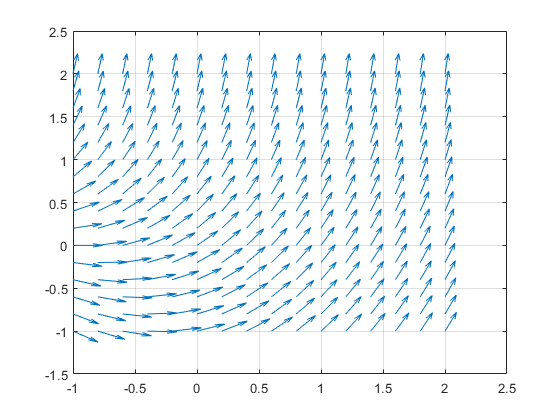

[t,y]=meshgrid(-1:0.2:2,-1:0.2:2);
u=ones(length(t));
v=f(t,y);
l=sqrt(1+v.^2);
quiver(t,y,u./l,v./l)
grid on